
% PNAS2024_Energy_cost_DNA_Nanopore


lp = 38; % nm, persistence length
lpd = 1; % nm, persistence length in defective region
D_exp = 5; %nm the 
E_exp = 18; % Energy cost in experiment in experiment.

Set up for excitation energy


T= 30; %°C
rhos = 1;% M salt concentration
D_DNA = 2; %nm, DNA diameter
D=D_exp - D_DNA; %
a = 0.34;
l = pi*D;
theta0 = 25/180*pi;
Ed=8.7/(49.2*rhos+1)-0.11*T+15.9;
E_circle = 2*pi^2*lp./l;
disp("In this case Ed = "+ Ed + "k_BT")

In this case Ed = 12.7733k_BT


E_kink2 = @(alpha,lpd) 0.5*lpd/a.*(theta0-2*alpha).^2+Ed;
E_kink1 = @(D,alpha,l,lpd) lp.*(pi-2*alpha)./(D).*(1-sin(pi-alpha)) ...
   +0.5*lpd/a.*(theta0-2*alpha).^2+Ed;

% yline(E_circle)
% hold on

alpha = 0:0.001:pi/2;
Alpha_tot =alpha;
Energy_tot = E_kink1(D,alpha,l,lpd);
plot(Alpha_tot/pi*180*2,Energy_tot)
[E_m,pos_m] =  min(Energy_tot);
hold on
plot(Alpha_tot(pos_m)/pi*180*2,E_m,'o')
yline(E_circle/2)
xlabel('Defect angle (deg)')
ylabel('Energy $(k_\mathrm{B}T)$',"Interpreter","latex")
title( "Diameter of the nanopore (experiment) " +D_exp + "nm")
legend('Enery cost','WLC','Theoretical prediction')

disp("the optimal defect angle is "+ Alpha_tot(pos_m)/pi*180*2+ "(deg)")

the optimal defect angle is 120.6649(deg)


disp("the energy cost is "+ E_m+ "(k_BT)")

the energy cost is 18.5925(k_BT)


Ed_exp = E_exp -(E_m-Ed);
disp("Ed (based on Experiment) = " + Ed_exp +"(k_BT)")

Ed (based on Experiment) = 12.1808(k_BT)


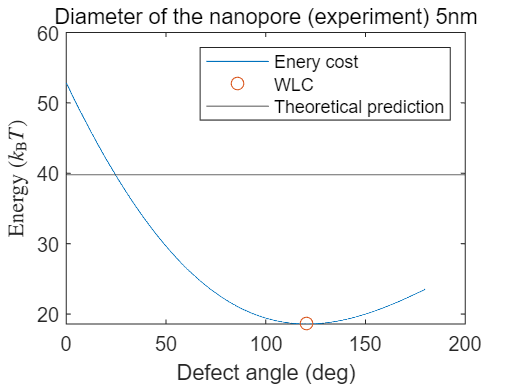


hold off

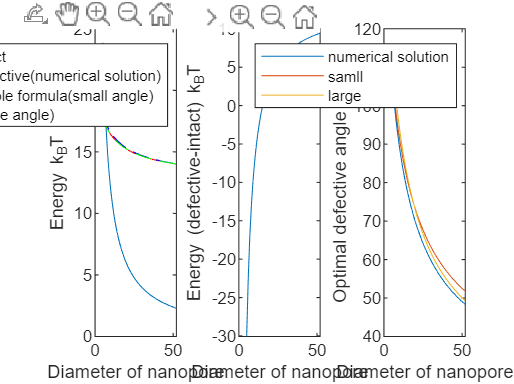


D_min =3 ;% the min diameter
D_step =1 ;% step length of D_min to D_max
D_max =50 ; % the max diameter 

f_math =@(D) (a*lp*(lp*(-16+16*pi-3*pi^2)+32*Ed*D)+16*lpd*D.*(2*Ed*D-lp*(pi-theta0)*(-2+theta0)))./ ...
    (32*D.*(a*lp+lpd*D));
theta0_large = @(D) (3*a*lp*pi+4*lpd*D)/(3*a*lp) - 2/3*sqrt(2)*sqrt( ...
    3*a*lp*lpd*pi*D+2*lpd^2*D.^2 -3*a*lp*lpd*D*theta0)/a/lp;
theta0_small = @(D) (2*a*lp+a*lp*pi+2*lpd*D*theta0 )./ (2*a*lp+2*lpd*D);

j1=1;
D = (D_min : D_step : D_max)+D_DNA;
collect1=zeros(length(D),3);
l = pi*D;
E_circle = 2*pi^2*lp./l;
for D1=D
Energy_tot = E_kink1(D1,alpha,l,lpd);
[min_E,pos] = min(Energy_tot);
min_theta_defect = alpha(pos)*2;
collect1(j1,:) = [D1,min_E,min_theta_defect];
j1=j1+1;
end


subplot(1,3,1)
plot(D,E_circle/2)
hold on
plot(D,collect1(:,2),'r')
plot(D,f_math(D),'b--')
plot(D,E_kink1(D,theta0_large(D)/2,l,lpd),'g--')
xlabel('Diameter of nanopore')
ylabel('Energy k_BT')
legend('intact','defective(numerical solution)','simple formula(small angle)','(large angle)')

subplot(1,3,2)
plot(D,collect1(:,2) - E_circle')
xlabel('Diameter of nanopore')
ylabel('Energy (defective-intact) k_BT')
subplot(1,3,3)

plot(D,collect1(:,3)/pi*180)
hold on
plot(D,theta0_large(D)/pi*180)
plot(D,theta0_small(D)/pi*180)
legend('numerical solution','samll','large')
xlabel('Diameter of nanopore')
ylabel('Optimal defective angle (deg)')


origin_collect=[D;E_circle/2;collect1(:,2)' - E_circle; collect1(:,3)'/pi*180]';
